# Smooth and Stable Greeks for Autocallables 

This is the live-script that showcases the capabilities of the Smooth and Smooth Symbolic pathwise estimators. All Estimators are initalized with a set of parameters embedded in the `AutoCallParams` class. We will initialize a 3-dimensional parameter set with one observation window, and a 2-dimensional with 2 timesteps. 

params_3d = AutoCallParams.test_instance_dim_3()

params_3d = s0 =

     1
     1
     1


risk_free =

    0.0500


sigma =

    0.1000
    0.2000
    0.0500


barrier =

    1.0500


correlation_matrix =

    1.0000    0.9000    0.5000
    0.9000    1.0000    0.4000
    0.5000    0.4000    1.0000


rebates =

    0.0500


payoff =

  function_handle with value:

    @(s)(sum(s-1))


windows =

     1


params_2d = AutoCallParams.test_instance_dim_2()

params_2d = s0 =

     1
     1


risk_free =

    0.0500


sigma =

    0.1000
    0.2000


barrier =

    1.0500


correlation_matrix =

    1.0000    0.9000
    0.9000    1.0000


rebates =

    0.0500    0.1000


payoff =

  function_handle with value:

    @(s)(sum(s-1))


windows =

     1     2


We will observe three Estimators: the Benchmark `NaivePathGenerator` naive Monte Carlo Estimator without any modifciations, the `SmoothPathGenerator` Stable Estimator, that is smooth and stable in finite difference methods, and finally `FastSymPaGe`, the modified smooth stable symbolic estimator. All the aforementioned classes are sub-classes of the abstract `pathGenerator` class that governs standard methods. Note that the initialization of `FastSymPaGe` is non-trivial in terms of setup times. This is because on intialization, symbolic calculations and derivations are performed. In an earlier version (`SmoothSymbolicPathGenerator`) a method based on Substition first and derivation second was implemented, which unfortunately did suffer tremendously from long sample times for higher order derivatives, and resulted in intialization times of up to 30 minutes. `FastSymPaGe` circumvents this issue by first building up a nested `SymTerm` - `GaussIntegral` structure before deriving these using the Leibnitz Rule with the `diff` and proprietary `leibnitz` methods. This massively improves intialization and sampling speed. 

smooth_2d = SmoothPathGenerator(params_2d);
smooth_3d = SmoothPathGenerator(params_3d);
naive_2d = NaivePathGenerator(params_2d);
naive_3d = NaivePathGenerator(params_3d);

fasy_2d = FastSySmPaGe(params_2d);

fasy_3d = FastSySmPaGe(params_3d);

## Tests

We will split the testing into two parts. First, we observe the standard deviations of the estimators for any sample path (`monte`), the first derivative (`deltas`) and the second (`gammas`). Then, we will look at the sampling times. 

### Standard Deviations

The tests are conducted separtely for outright path estimation, Delta and Gamma. We observe lower standard deviation for the `smooth` and `fasy` estimators compared to the `naive` method. The histograms validate the intuitive notion that the method redistributes upside to the downside, overall reducing payoff variance. 

### Payoff Estimates

The new method clearly outperforms the naive estimator in terms of variance reduction. However, this comes at the cost of a higher number of samples, as the smooth and stable method requires $K$ subsamples each timestep. In addtion, the higher complexity of the importance sampling splitting results in generally higher computation times

monts = zeros(3,10000);
parfor i = 1:10000
    monts(:, i) = [naive_3d.samplePathPayoff(); ...
         smooth_3d.samplePathPayoff();...
         fasy_3d.samplePathPayoff()];
end
Method = {'Naive'; 'Smooth Stable'; 'Symbolic Smooth Stable'};
Mean_Estimate = mean(monts, 2);
Standard_Deviation = std(monts, 0, 2);
Skew = skewness(monts, 1, 2);
Kurtosis = kurtosis(monts, 1,2);
T = table(Mean_Estimate, Standard_Deviation, Skew, Kurtosis);
T.Properties.RowNames = Method;
T.Properties.VariableNames = {'Mean Estimate'; 'Standard Deviation'; 'Skew'; 'Kurtosis'};
T

T = 3×4 table
                              Mean Estimate    Standard Deviation     Skew      Kurtosis
                              _____________    __________________    _______    ________

    Naive                       0.023425            0.19978          0.13796     5.0065 
    Smooth Stable               0.022437            0.11706          0.40029     4.1121 
    Symbolic Smooth Stable      0.028165            0.11698          0.52142     4.4383 


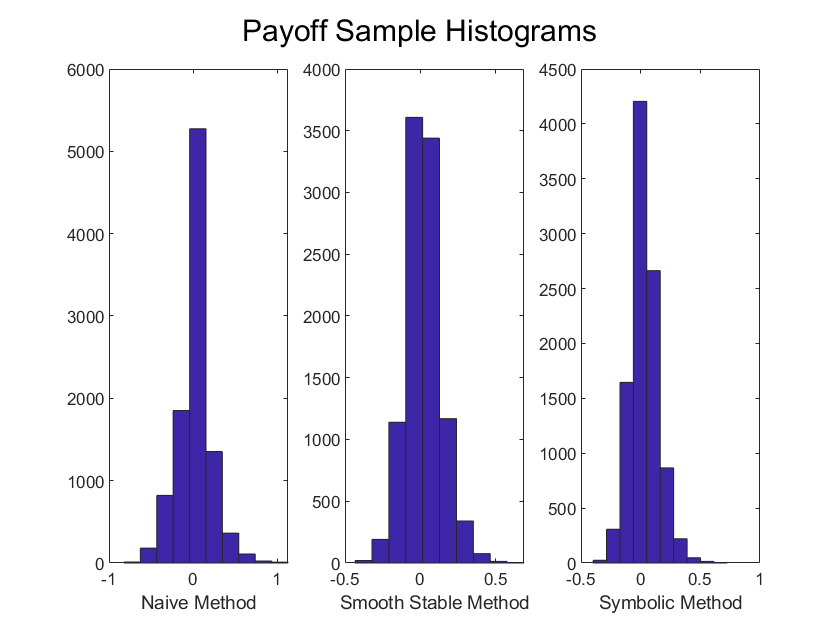

figure; 
ax1 = subplot(1, 3, 1);
title('Naive Method');
hist(ax1, monts(1,:));
xlabel('Naive Method')
ax2 = subplot(1, 3, 2);
title('Smooth Stable Method');
hist(ax2, monts(2, :));
xlabel('Smooth Stable Method')
ax3 = subplot(1, 3, 3);
hist(ax3, monts(3, :));
title('Symbolic Smooth Stable Method');
hist(ax3, monts(3, :));
xlabel('Symbolic Method')
sgtitle('Payoff Sample Histograms');

### Delta Estimation

The power of the smooth stable estimator is visible for both finite differences and pathwise methds. The former has roughly half the standard deviation of the naive estimator.

The pathwise method is even more successful, having almost 40x less standard deviation than the naive method. Sample variance is of crucial importance to estimate the required $N$ for a certain estimator standrad deviation $p$, as $N \ge p^{-2} \sigma^2$ following the central limit theorem. 

deltas = zeros(3,10000);
parfor i = 1:10000
    deltas(:, i) = [naive_3d.Delta(1,0.01,1); ... 
        smooth_3d.Delta(1,0.01,1); %...
         fasy_3d.Delta(1,0.01,1)];
end
Method = {'Naive (FD)'; 'Smooth Stable (FD)'; 'Symbolic Smooth Stable (Pathwise)'};
Mean_Estimate = mean(deltas, 2);
Standard_Deviation = std(deltas, 0, 2);
Skew = skewness(deltas, 1, 2);
Kurtosis = kurtosis(deltas, 1,2);
T = table(Mean_Estimate, Standard_Deviation, Skew, Kurtosis);
T.Properties.RowNames = Method;
T.Properties.VariableNames = {'Mean Estimate'; 'Standard Deviation'; 'Skew'; 'Kurtosis'};
T

T = 3×4 table
                                         Mean Estimate    Standard Deviation       Skew       Kurtosis
                                         _____________    __________________    __________    ________

    Naive (FD)                               0.2031             29.219            0.041784     4.2123 
    Smooth Stable (FD)                      0.53809             16.926          -0.0041516     3.5822 
    Symbolic Smooth Stable (Pathwise)       0.57503            0.78325            0.043547     3.1856 


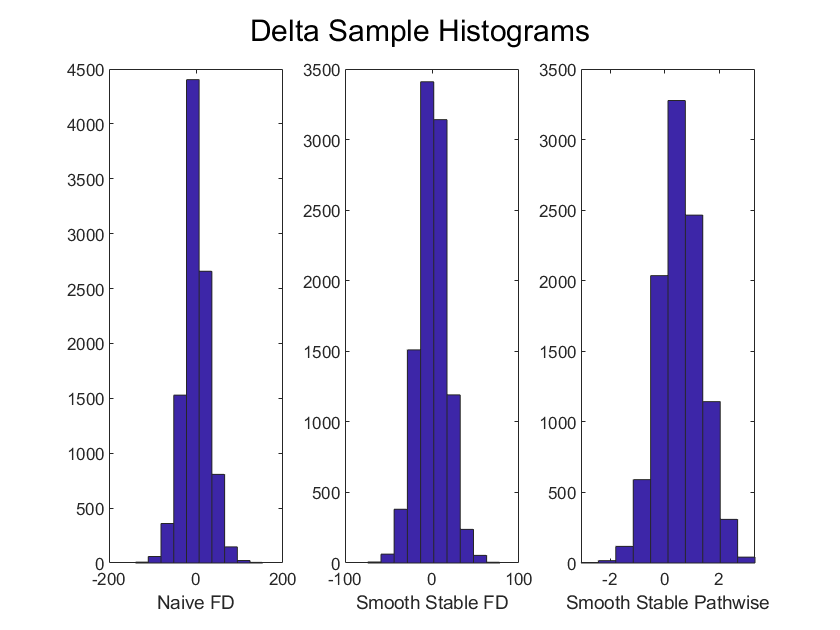

figure(2)
ax1 = subplot(1, 3, 1);
hist(ax1, deltas(1,:));
xlabel('Naive FD')
ax2 = subplot(1, 3, 2);
hist(ax2, deltas(2, :));
xlabel('Smooth Stable FD')
ax3 = subplot(1,  3, 3);
hist(ax3, deltas(3, :));
xlabel(['Smooth Stable Pathwise']);
sgtitle('Delta Sample Histograms');

### Gamma

Again, the Symbolic pathwise estimator performs best, with the effects even more drastic than for the first order derivative estimator. Following the CLT, an estimator standard deviation of 0.1 would be achievable with ~7,500 samples, while the naive estimator would require 2.5bn samples to achieve the same standard deviation. 

The mixture estimator that applies finite differences to the symbolic estimator has 50x less variance than the naive method but is significantly worse in performance versus the pure pathwise method. 

It has to be noted that pathwise method has the most pronounced skew out of the methods, while kurtoses are approximately normal for all estimators. 

gammas = zeros(4,10000);
parfor i = 1:10000
    gammas(:, i) = [naive_3d.Gamma(1,0.01,1); ... 
        smooth_3d.Gamma(1,0.01,1); %...
         fasy_3d.Gamma(1,0.01,1);
         fasy_3d.fd_Gamma(1, 0.01, 1)]
end
Method = {'Naive (FD)'; 'Smooth Stable (FD)'; 'Symbolic Smooth Stable (Pathwise)'; 'Symbolic Smooth Stable (Mixture)'};
Mean_Estimate = mean(gammas, 2);
Standard_Deviation = std(gammas, 0, 2);
Skew = skewness(gammas, 1, 2);
Kurtosis = kurtosis(gammas, 1,2);
T = table(Mean_Estimate, Standard_Deviation, Skew, Kurtosis);
T.Properties.RowNames = Method;
T.Properties.VariableNames = {'Mean Estimate'; 'Standard Deviation'; 'Skew'; 'Kurtosis'};
T

T = 4×4 table
                                         Mean Estimate    Standard Deviation      Skew       Kurtosis
                                         _____________    __________________    _________    ________

    Naive (FD)                              -18.553               5037           -0.11062     4.1562 
    Smooth Stable (FD)                      -1.6826             2882.6            -0.1904     3.5259 
    Symbolic Smooth Stable (Pathwise)        2.4744             8.5303           -0.24589     3.1102 
    Symbolic Smooth Stable (Mixture)         1.9344             100.26          -0.022227     3.0504 


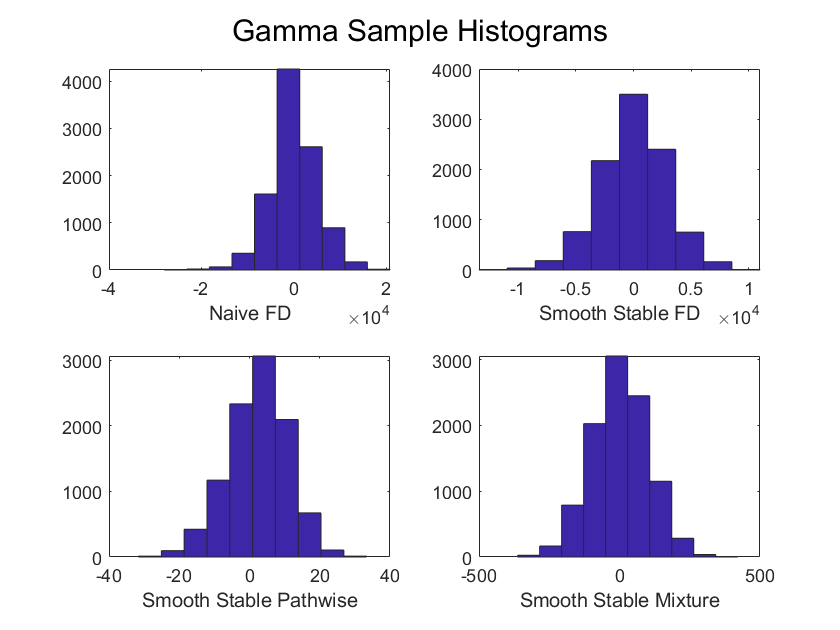

figure; 
ax1 = subplot(2, 2, 1);
hist(ax1, gammas(1,:));
xlabel('Naive FD')
ax2 = subplot(2, 2, 2);
hist(ax2, gammas(2, :));
xlabel('Smooth Stable FD')
ax3 = subplot(2, 2, 3);
hist(ax3, gammas(3, :));
xlabel('Smooth Stable Pathwise')
ax4 = subplot(2, 2, 4);
hist(ax4, gammas(4, :));
xlabel('Smooth Stable Mixture')
sgtitle('Gamma Sample Histograms');

## Sample Runtime

The increased precision of the estimators comes with the cost of higher runtime. As noted above, we are able to front load some of the runtime into the object initialization for the Symbolic methods, which leads to considerable performance improvements. Note however that the execution time of the naive method scales linearly with the number of observation windows, whereas it is cubic for the smooth stable estimators. 

### 3-dimensions and 1 observation window

We find tha tthe symbolic estimator outperforms the naive estimator from the first order derivative. 

Payoff = [timeit(@() naive_3d.samplePathPayoff()); timeit(@() smooth_3d.samplePathPayoff());timeit(@() fasy_3d.samplePathPayoff())];
Delta = [ timeit(@()naive_3d.Delta(1, 0.1, 1)); timeit(@() smooth_3d.Delta(1, 0.1, 1));timeit(@() fasy_3d.Delta(1, 0.1, 1))];
Gamma = [timeit(@() naive_3d.Gamma(1, 0.1, 1)); timeit(@() smooth_3d.Gamma(1, 0.1, 1));timeit(@() fasy_3d.Gamma(1, 0.1, 1))];
Method = {'Naive (FD)'; 'Smooth Stable (FD)'; 'Symbolic Smooth Stable (Pathwise)'};
T = table(Payoff, Delta, Gamma);
T.Properties.RowNames = Method;
T

T = 3×3 table
                                           Payoff        Delta         Gamma  
                                         __________    __________    _________

    Naive (FD)                           1.5567e-05     0.0012029    0.0022078
    Smooth Stable (FD)                    0.0012748     0.0035255     0.005622
    Symbolic Smooth Stable (Pathwise)    0.00029317    0.00053447    0.0012493


### 2-dimensions and 2 observation windows

We find that the naive method remains the quickest in terms of estimation, with the pathwise estimator in second place and the smooth stable estimator the slowest in third place. 

Payoff = [timeit(@() naive_2d.samplePathPayoff()); timeit(@() smooth_2d.samplePathPayoff());timeit(@() fasy_2d.samplePathPayoff())];
Delta = [ timeit(@()naive_2d.Delta(1, 0.1, 1)); timeit(@() smooth_2d.Delta(1, 0.1, 1));timeit(@() fasy_2d.Delta(1, 0.1, 1))];
Gamma = [timeit(@() naive_2d.Gamma(1, 0.1, 1)); timeit(@() smooth_2d.Gamma(1, 0.1, 1));timeit(@() fasy_2d.Gamma(1, 0.1, 1))];
Method = {'Naive (FD)'; 'Smooth Stable (FD)'; 'Symbolic Smooth Stable (Pathwise)'};
T = table(Payoff, Delta, Gamma);
T.Properties.RowNames = Method;
T

T = 3×3 table
                                           Payoff        Delta         Gamma  
                                         __________    __________    _________

    Naive (FD)                           2.6067e-05    0.00099527    0.0018445
    Smooth Stable (FD)                     0.001668     0.0048279    0.0089398
    Symbolic Smooth Stable (Pathwise)     0.0010837      0.002494    0.0051419


## Path-recycling

Path-recycling means using the same random variables for the finite difference calculation and then averaging. This is particuallry effective for the smooth-stable methods. The naive method improves in performance but developes a non-continuous distribution, due to the discontinuities in the path-evaluation. 

gammas = zeros(4,10000);
parfor i = 1:10000
    gammas(:, i) = [naive_3d.pr_Gamma(1,0.01,1); ... 
        smooth_3d.pr_Gamma(1,0.01,1); %...
         fasy_3d.Gamma(1,0.01, 1);
         fasy_3d.pr_Gamma(1,0.01, 1)];
end
Method = {'Naive (FD)'; 'Smooth Stable (FD)'; 'Symbolic Smooth Stable (Pathwise)'; 'Symbolic Smooth Stable (Mixture)'};
Mean_Estimate = mean(gammas, 2);
Standard_Deviation = std(gammas, 0, 2);
Skew = skewness(gammas, 1, 2);
Kurtosis = kurtosis(gammas, 1,2);
T = table(Mean_Estimate, Standard_Deviation, Skew, Kurtosis);
T.Properties.RowNames = Method;
T.Properties.VariableNames = {'Mean Estimate'; 'Standard Deviation'; 'Skew'; 'Kurtosis'};
T

T = 4×4 table
                                         Mean Estimate    Standard Deviation      Skew       Kurtosis
                                         _____________    __________________    _________    ________

    Naive (FD)                              106.62              534.54             1.2068     8.9098 
    Smooth Stable (FD)                      4.3283              20.649           -0.03841      2.882 
    Symbolic Smooth Stable (Pathwise)       2.6056               8.481           -0.22945     3.0883 
    Symbolic Smooth Stable (Mixture)        2.0775               14.25          -0.074479     2.9838 


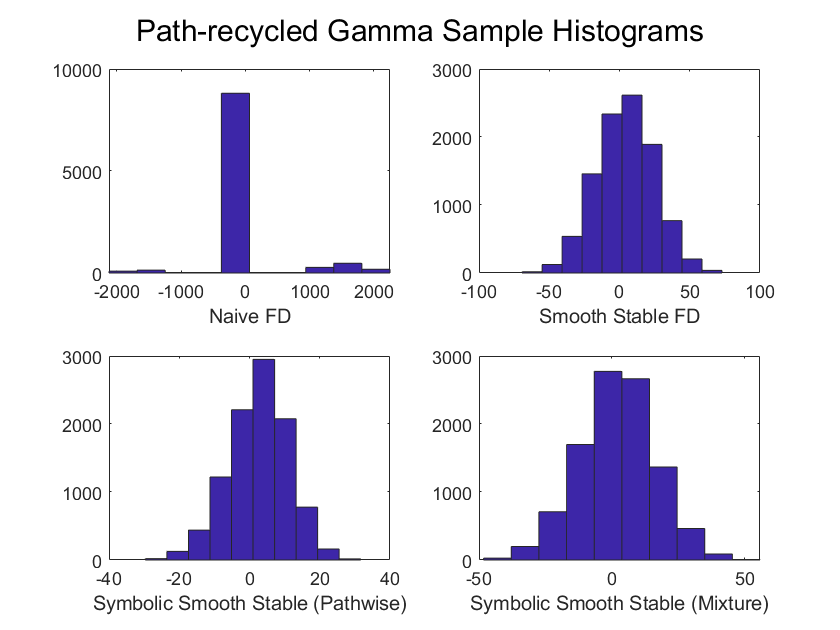

figure; 
ax1 = subplot(2, 2, 1);
hist(ax1, gammas(1,:));
xlabel('Naive FD')
ax2 = subplot(2, 2, 2);
hist(ax2, gammas(2, :));
xlabel('Smooth Stable FD')
ax3 = subplot(2, 2, 3);
hist(ax3, gammas(3, :));
xlabel('Symbolic Smooth Stable (Pathwise)')
ax4 = subplot(2, 2, 4);
hist(ax4, gammas(4, :));
xlabel('Symbolic Smooth Stable (Mixture)')
sgtitle('Path-recycled Gamma Sample Histograms');

# Conclusions

We find that the smooth stable estimators outperform the naive estimators in terms of sample precision in all cases. While the naive esitmator remains the fastest, it's lack of precision makes it effectively unusable for higher order derivatives like Gamma. The smooth stable finite differences estimator improves the sampling precision but is not as precise and fast as the symbolic pathwise estimator, which performs best in all cases. 

Further, path-recycling improves the smooth-stable estimators, such that they are similar in performance to the pathwise method. 